**Essentials of Ultrasound Imaging: Lecture 4**

**GUI: Fourier  Transform Calculator**

**Author: Joseph Greene**

**Reference: Chapter 2.2, Fourier Transform/ Appendix A**

Brief Description: In this Live Editor, we will discuss how we may depict the Fourier Transform of a signal.

Inputs: Signal type, Fourier Transform Type, Tone Burst Frequency, Gaussian Variance, Super-Gaussian Variance, Super-Gaussian Order, Delta Center Time

Outputs: Frequency Spectrum (Graph)

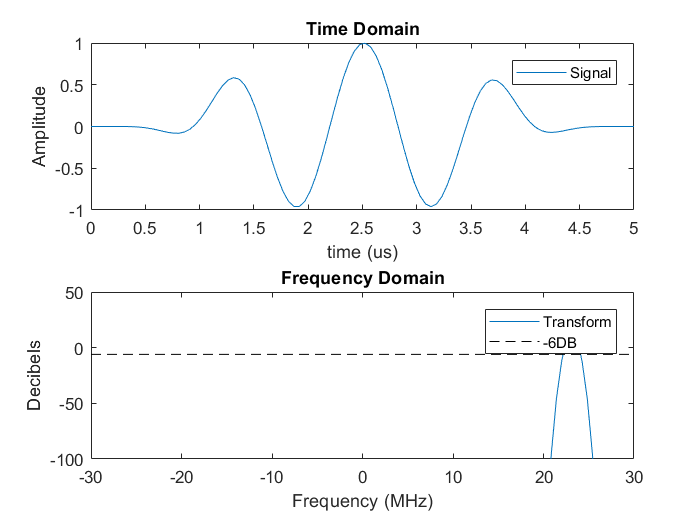

%%%%%%%%%%%%
%User Inputs
%%%%%%%%%%%%
%{
 Choose a Original Signal
    0: Tone Burst
    1: Gaussian
    2: Super-Gaussian
    3: Delta
%}
Signal_type = 2;

%{
 Choose a method of calculating the Fourier transform
    0: Padded FFT - Standard Numerical Practice for MATLAB -> Recall FFT is a CIRCULANT dft! [That's why its padded]
    1: Continuous Fourier Transform: The function generated by deriving a nondiscretized signal [This is the ideal result]
%}
Type_Transform = 1;

%Tone Burst Properties
freq = 5; %MHz

%Gaussian Properties
var = 2; %Sigma squared in gaussian formula
mod = 5; %Modulation frequency - keep between 5-10MHz

%Super-Gaussian Properties
var_SG = 2;
order = 2;
mod = 5;

%Delta
center = 2.5; %Center in time - put value between 0 and 5

n = 100; %Number of samples in time domain
T = linspace(0,5,n); %Time Domain Range in us


%%%%%%%%%%%%%%%%
%Generate Graphs
%%%%%%%%%%%%%%%%
%Calculate frequency domain using the fact that dx*du = 2*pi
F = linspace(-pi/(1/(0.1*n-1)),pi/(1/(0.1*n-1)),n); %Freq domain sampling  
%Define useful equations
Ft = @(x) fftshift(fft(x,2*n)); %1D Fourier transform. The second argument pads original signal to reduce artifacts by circulant nature of FFT.
S = @(f) cos(f*T); %Tone Burst
G = @(v,f) 1*exp(-((T-2.5)./sqrt(var)).^2).*cos(f*T); %Gaussian centered at 2.5 us
SG = @(v,o,f) (1*exp(-((T-2.5)./sqrt(var)).^(2*o))).*cos(f*T); %Standard gaussian to the o-th power

if Signal_type == 0
    signal = S(freq);
    if Type_Transform == 0
        transform = abs(Ft(signal));
        %Remove padding
        transform = mag2db(transform((round(n/2)+1):(round(3*n/2))));
    else
        %For cos, CFT is two deltas at the desired +- frequency values
        transform = zeros(1,n)-60;
        [minValPos, ClosestIndexPos] = min(abs(F-freq*ones(size(F))));
        [minValNeg, ClosestIndexNeg] = min(abs(F+freq*ones(size(F))));
        transform(1,[ClosestIndexNeg,ClosestIndexPos]) = mag2db(1);
    end
    
elseif Signal_type == 1
    signal = G(var,mod);
    if Type_Transform == 0
        transform = abs(Ft(signal));
        %Remove padding
        transform = mag2db(transform((round(n/2)+1):(round(3*n/2))));
    else
        transform = mag2db(sqrt(pi*var)*exp(-(pi*(F-mod)./sqrt(var)).^2)+sqrt(pi*var)*exp(-(pi*(F+mod)./sqrt(var)).^2));
    end
    
elseif Signal_type == 2
     signal = SG(var_SG, order,mod);
    if Type_Transform == 0
        transform = abs(Ft(signal));
        %Remove padding
        transform = mag2db(transform((round(n/2)+1):(round(3*n/2))));
    else
        %Recall that multiplication in one domain is convolution in the other! A super gaussian is o gaussians multiplied together so the Fourier transform would be...
        transform = zeros(1,n);
        [minValPos, ClosestIndexPos] = min(abs(F-mod));
        [minValNeg, ClosestIndexNeg] = min(abs(F+mod));
        transform(1,[ClosestIndexNeg,ClosestIndexPos]) = 1;
        for i = 1:order
            transform = conv(transform,sqrt(pi*var_SG)*exp(-(pi*F./sqrt(var_SG)).^2));
        end
        %Now convolving will increase the length of the array so we cut it down to the signal length
        transform = mag2db(transform(order/2*n-n/2+1:order/2*n+n/2));
    end 
     
else
    [minVal, minIndex] = min(abs(center-T))
    signal = zeros(size(T)); %Define zeros
    signal(minIndex) = 1; %Assign single point to one
    if Type_Transform == 0
        transform = abs(Ft(signal));
        %Remove padding
        transform = mag2db((transform((round(n/2)+1):(round(3*n/2)))));
    else
        transform = mag2db(ones(1,length(F)));
    end
    
end

figure
subplot(2,1,1)
plot(T,signal)
title('Time Domain')
xlabel('time (us)')
ylabel('Amplitude')
legend('Signal')

subplot(2,1,2)
plot(F,transform) %Clip transform to remove padding
if Signal_type ~= 3 %Delta has a transform that is a line at 0, doesn't reach -6
    line([-30,30],[-6,-6],'Color','k','LineStyle','--')
    legend('Transform','-6DB')
else
    legend('Transform')
    axis([-30 30 -0.1 0.1]) %Bitwise error generated by fft creates shown fluctuations on the scale of 10^-15 - deceptive
end
title('Frequency Domain')
xlabel('Frequency (MHz)')
ylabel('Decibels')
axis([-30 30 -100 50])